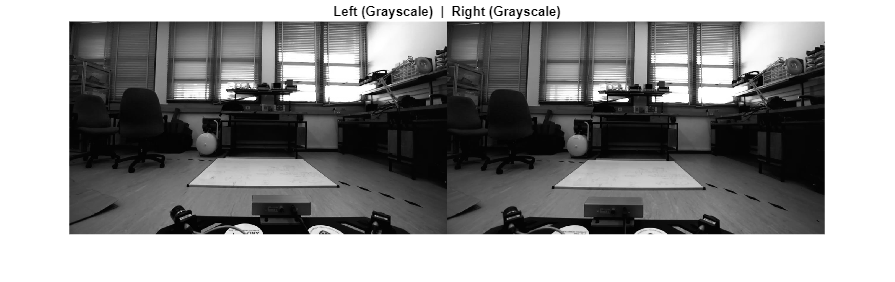

load('stereoParams.mat');
I1 = imread('Experiment_3\left\left_image_10.jpg');
I2 = imread('Experiment_3\right\right_image_10.jpg');
%imageSize1 = size(I1);
imageSize2 = size(I2);

%disp(['Size of left image (I1) raw: ', num2str(imageSize1)]);
%disp(['Size of right image (I2) raw: ', num2str(imageSize2)]);


[J1, J2] = rectifyStereoImages(I1,I2, stereoParams);
imageSize3 = size(J1);
imageSize4 = size(J2);

%disp(['Size of left image (J1) rectified: ', num2str(imageSize3)]);
%disp(['Size of right image (J2) rectified: ', num2str(imageSize4)]);


I1gray = rgb2gray(I1);
I2gray = rgb2gray(I2);
% Create a montage using the montage function
montage([I1gray, I2gray]);
% Optional: Add a title to the montage
title('Left (Grayscale)  |  Right (Grayscale)');

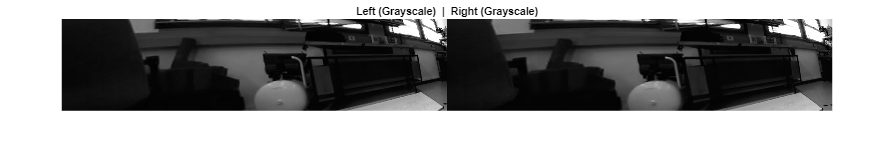

figure;
imshow(I1gray);
title('Select the region of interest (ROI) by drawing a polygon');
h1 = msgbox('Please select the region of interest in the image by drawing a polygon.');
uiwait(h1);
roiMask1 = roipoly;
close;


J1gray = rgb2gray(J1);
J2gray = rgb2gray(J2);
% Create a montage using the montage function
montage([J1gray, J2gray]);
% Optional: Add a title to the montage
title('Left (Grayscale)  |  Right (Grayscale)');

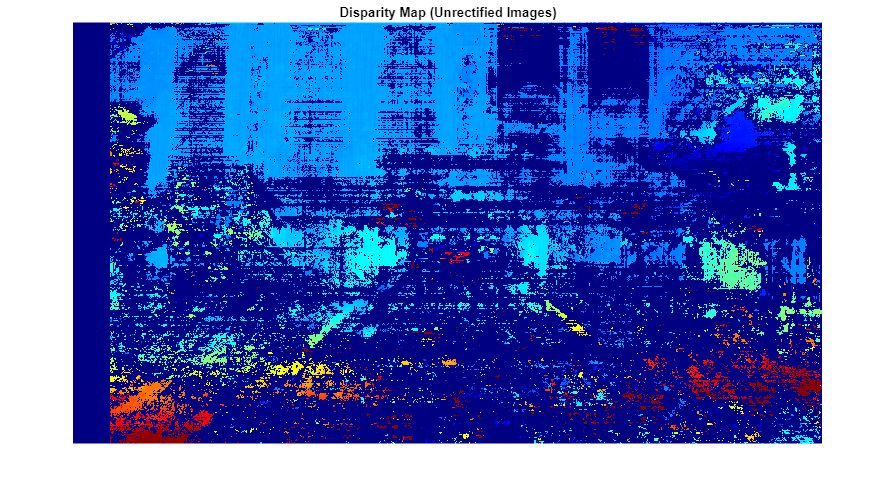


%Disparity map for unrectified image
disparityRange = [0 64];
disparityMap1 = disparitySGM(I1gray, I2gray, 'DisparityRange', disparityRange);
% Use imshow to display the disparity map
imshow(disparityMap1, disparityRange);

% Optional: Add a title and colormap
title('Disparity Map (Unrectified Images)');
colormap jet;  % Or choose another colormap like 'hot' or 'gray'


objectDisparity1 = disparityMap1 .* roiMask1;

Error using  .* 
Arrays have incompatible sizes for this operation.

Related documentation

validDisparity1 = objectDisparity1(objectDisparity1 > disparityRange(1) & objectDisparity1 < disparityRange(2));
imshow(validDisparity1,disparityRange)
title('Disparity Map(roiMask unrectified)')

figure;
imshow(J1gray);
title('Select the region of interest (ROI) by drawing a polygon');
h2 = msgbox('Please select the region of interest in the image by drawing a polygon.');
uiwait(h2);
roiMask2 = roipoly;
close;

%Disparity map for Rectified image
disparityRange = [0 64];
disparityMap2 = disparitySGM(J1gray, J2gray, 'DisparityRange', disparityRange);
% Use imshow to display the disparity map
imshow(disparityMap2, disparityRange);

% Optional: Add a title and colormap
title('Disparity Map (Rectified Images)');
colormap jet;  % Or choose another colormap like 'hot' or 'gray'
objectDisparity2 = disparityMap2 .* roiMask2;
validDisparity2 = objectDisparity2(objectDisparity2 > disparityRange(1) & objectDisparity2 < disparityRange(2));
imshow(validDisparity2,disparityRange)
title('Disparity Map(roiMask rectified)')

focalLength = stereoParams.CameraParameters1.FocalLength(1); % Focal length in pixels
baseline = norm(stereoParams.TranslationOfCamera2); % Baseline in meters

if isempty(validDisparity1)
    error('No valid disparity values found within the selected ROI.');
end

meanDisparity1 = mean(validDisparity1(:));

% Calculate distance
distance1 = (focalLength * baseline) / meanDisparity1;

% Calculate size
% Calculate size
roiStats1 = regionprops(roiMask1, 'BoundingBox');
if isempty(roiStats1)
    error('No bounding box found in the selected ROI.');
end
bbox1 = roiStats1.BoundingBox;
objectWidth1 = (bbox1(3) * distance1) / focalLength;
objectHeight1 = (bbox1(4) * distance1) / focalLength;

fprintf('Distance = %.2f centimeters, Width = %.2f centimenters, Height = %.2f centimeters\n', distance1, objectWidth1, objectHeight1);


focalLength = stereoParams.CameraParameters1.FocalLength(1); % Focal length in pixels
baseline = norm(stereoParams.TranslationOfCamera2); % Baseline in meters

if isempty(validDisparity2)
    error('No valid disparity values found within the selected ROI.');
end

meanDisparity2 = mean(validDisparity2(:));

% Calculate distance
distance2 = (focalLength * baseline) / meanDisparity2;

% Calculate size
roiStats2 = regionprops(roiMask2, 'BoundingBox');
bbox2 = roiStats2.BoundingBox;
objectWidth2 = (bbox2(3) * distance2) / focalLength;
objectHeight2 = (bbox2(4) * distance2) / focalLength;

fprintf('Distance = %.2f centimeters, Width = %.2f centimeters, Height = %.2f centimeters\n', distance2, objectWidth2, objectHeight2);
I1grayshape = insertShape(I1gray, 'Rectangle', bbox1, 'Color', 'green');
figure;
imshow(I1grayshape);
title(sprintf('Distance = %.2f meters, Width = %.2f meters, Height = %.2f meters', distance1, objectWidth2, objectHeight2));


J1grayshape = insertShape(J1gray, 'Rectangle', bbox2, 'Color', 'green');
figure;
imshow(J1grayshape);
title(sprintf('Distance = %.2f meters, Width = %.2f meters, Height = %.2f meters', distance2, objectWidth2, objectHeight2));
% Reconstruct the 3D point cloud
points3D1 = reconstructScene(disparityMap1, stereoParams);

% Mask the points to include only the ROI
points3D1 = points3D1 .* repmat(roiMask1, [1, 1, 3]);

% Remove points with no disparity (they are at infinity)
points3D1 = points3D1(all(points3D1 ~= 0, 3));

% Convert from millimeters to meters
points3D1 = points3D1 / 1000;

% Display the 3D point cloud
figure;
pcshow(points3D1, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down');
title('Reconstructed 3D Point Cloud of the Object');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

% Fit a surface to the point cloud
% For simplicity, we use a convex hull to approximate the shape
k = convhull(points3D1(:,1), points3D1(:,2), points3D1(:,3));

figure;
trisurf(k, points3D1(:,1), points3D1(:,2), points3D1(:,3), 'FaceColor', 'cyan', 'EdgeColor', 'none');
title('Estimated Shape of the Object');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
% Reconstruct the 3D point cloud
points3D2= reconstructScene(disparityMap2, stereoParams);

% Mask the points to include only the ROI
points3D2 = points3D2 .* repmat(roiMask2, [1, 1, 3]);

% Remove points with no disparity (they are at infinity)
points3D2 = points3D2(all(points3D2 ~= 0, 3));

% Convert from millimeters to meters
points3D2 = points3D2 / 1000;

% Display the 3D point cloud
figure;
pcshow(points3D2, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down');
title('Reconstructed 3D Point Cloud of the Object');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

% Fit a surface to the point cloud
% For simplicity, we use a convex hull to approximate the shape
k = convhull(points3D2(:,1), points3D2(:,2), points3D2(:,3));

figure;
trisurf(k, points3D2(:,1), points3D2(:,2), points3D2(:,3), 'FaceColor', 'cyan', 'EdgeColor', 'none');
title('Estimated Shape of the Object');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');



